%RBE501_FINALEXAM
%Ali Abdelhamid 12/9/2020
clear 
close all
clc


## ROBOT IN HOME POSITION SHOWING FRAME ASSIGNMENT

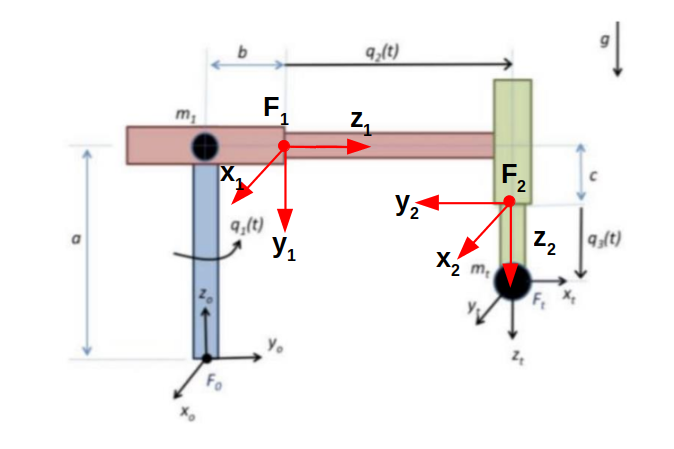

# PART A, LAGRANGE APPROACH

## POE FWD KIN

%M and Slist derrived from robot in home position (all thetas = 0):

%here m2 is 0 and mt is mass at tool tip
syms a b c m1 m2 mt real
syms q1 q2 q3 real

%Assuming EE frame is in same orientation as base frame at home position
M = [0,1,0,0;
    1,0,0,b;
    0,0,-1,a-c;
    0,0,0,1];

Slist = [[0;0;1;0;0;0],[0;0;0;0;1;0],[0;0;0;0;0;-1]];

thetalist = [q1; q2; q3];

%Iterative loop for deriving array of ES matrixes 
I = eye(3);  %identity matrix
T = {};      %define T as an array to store all ES matrixes

for i = 1 : length(thetalist)
    w = skew(Slist(1:3,i));
    v = Slist(4:6,i);
    theta = thetalist(i);
    
    R = I + sin(theta)*w + (1-cos(theta))*w^2;
    
    star = (I*theta + (1-cos(theta))*w + (theta-sin(theta))*w^2)*v;
    
    T{i} = [R star; 0 0 0 1];
end




## BASE FRAME TO TOOL FRAME TRANSFORMATION MATRIX

%Now we can use the T matrix to derive the transformation matrix from the base
%frame to the tool frame for calculating the joint velocities in order to
%get the kinetic energy component for Lagrangian. 
%Note that even though frame 1 is not on top of m1 (as in HW3), we do not need 
%to worry about m1's kinetic energy because it sits on top of link 1 which can 
%have no linear velocity (joint 1 is a revolute joint). 
%Also note that even though m1 can technically rotate, it is a point mass and 
%this does not have Kinetic energy due to angular velocity (it just spins in place). 
%Finally, m1 potential energy is 0 because it can not fall "into" link 1...

%Transformation matrices from base frame to frame (i) on top of joint (i+1)
M0_1 = [1,0,0,0;
        0,0,1,b;
        0,-1,0,a;
        0,0,0,1];
T0_1 = simplify(T{1}*M0_1);

M0_2 = [1,0,0,0;
        0,-1,0,b;
        0,0,-1,a-c;
        0,0,0,1];
T0_2 = simplify(T{1}*T{2}*M0_2);

M0_tool = M;
T0_tool = simplify(T{1}*T{2}*T{3}*M0_tool);
T0_3 = T0_tool;

P_tool = T0_tool(1:3,4);

%Transformation matrices from base frame to each mass since even though 
%the masses are not at COM, there are offsets we have to factor in
T1_c1 = [1,0,0,0;
         0,1,0,0;
         0,0,1,-b;
         0,0,0,1];
T0_c1 = simplify(T0_1*T1_c1);

T2_c2 = [1,0,0,0;
         0,1,0,0;
         0,0,1,-c;
         0,0,0,1];
T0_c2 = simplify(T0_2*T2_c2);

T3_c3 = [1,0,0,0;
         0,1,0,0;
         0,0,1,0;
         0,0,0,1];
T0_c3 = simplify(T0_3*T3_c3);


## CALCULATING INDIVIDUAL JACOBIANS FOR INDIVIDUAL KINETIC ENERGIES

%Note that we only solve for upper half of Jacobian since kinetic energy
%due to angular velocity is 0 (and thus Dw is 0) because inertia is 0 for
%this problem
Oc1 = T0_c1(1:3,4);
Jv_c1 = jacobian(Oc1, [q1 q2 q3]);

Oc2 = T0_c2(1:3,4);
Jv_c2 = jacobian(Oc2, [q1 q2 q3]);

Oc3 = T0_c3(1:3,4);
Jv_c3 = jacobian(Oc3, [q1 q2 q3]);


## CALCULATING VELOCITIES OF EACH MASS

syms q_dot_1 q_dot_2 q_dot_3 q_ddot_1 q_ddot_2 q_ddot_3 real

q = [q1; q2; q3;];
q_d = [q_dot_1; q_dot_2; q_dot_3;];
q_dd = [q_ddot_1; q_ddot_2; q_ddot_3;];

Vel_1 = chainRule(Oc1,q,q_d,q_dd);
Vel_2 = chainRule(Oc2,q,q_d,q_dd);
Vel_3 = chainRule(Oc3,q,q_d,q_dd);


## FIND LANGRANGIAN TERM

%compute kinetic energies
K1 = 0.5 * m1 * Vel_1.' * Vel_1;
K2 = 0.5 * m2 * Vel_2.' * Vel_2; %general form, but m2 will be substituted with 0
K3 = 0.5 * mt * Vel_3.' * Vel_3; 
KE = K1 + K2 + K3; %total kinetic energy

%compute potential energies
syms g real
P1 = m1*g*T0_c1(3,4);
P2 = m2*g*T0_c2(3,4); %general form, but m2 will be substituted with 0
P3 = mt*g*T0_c3(3,4);
PE = P1 + P2 + P3;

%Langrangian Term
L = simplify(KE-PE);




## FIND $\tau_i =\frac{d}{\mathrm{dt}}\left(\frac{\delta L}{\delta \dot{\;q_i } }\right)-\left(\frac{\delta L}{\delta q_i }\right)\;$

where $\left(\frac{\delta L}{\delta \dot{\;q_i } }\right)$=xi 

and $\frac{d}{\mathrm{dt}}\left(\frac{\delta L}{\delta \dot{\;q_i } }\right)$=yi

and $\left(\frac{\delta L}{\delta q_i }\right)$=zi

x1 = diff(L, q_dot_1);
x2 = diff(L, q_dot_2);
x3 = diff(L, q_dot_3);

y1 = chainRule(x1, q, q_d, q_dd);
y2 = chainRule(x2, q, q_d, q_dd);
y3 = chainRule(x3, q, q_d, q_dd);

z1 = diff(L,q1);
z2 = diff(L,q2);
z3 = diff(L,q3);

Tau_1 = simplify(y1-z1);
Tau_2 = simplify(y2-z2);
Tau_3 = simplify(y3-z3);

Tau_Lagrangian_General = [Tau_1;Tau_2;Tau_3];
Tau_Lagrangian = subs(Tau_Lagrangian_General, m2, 0)

$$Tau\_Lagrangian = \left(\begin{array}{c} \mathrm{mt}\,{\ddot{q}}_{1}\,{\left(b+q_{2}\right)}^{2}+2\,\mathrm{mt}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(b+q_{2}\right)\\ -\mathrm{mt}\,\left(b\,{{\dot{q}}_{1}}^{2}-{\ddot{q}}_{2}+q_{2}\,{{\dot{q}}_{1}}^{2}\right)\\ -\mathrm{mt}\,\left(g-{\ddot{q}}_{3}\right) \end{array}\right)$$

## FORMING DYNAMICAL MODEL OF ROBOT IN COMPACT FORM:


$$\tau =M\left(q\right)\overset{\cdot \cdot }{q} \;+C\left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} \;+G\left(q\right)$$


### BUILDING INERTIA MATRIX (M)

M11 = simplify(Tau_1 - subs(Tau_1,q_ddot_1,0)) /q_ddot_1;
M12 = simplify(Tau_1 - subs(Tau_1,q_ddot_2,0)) /q_ddot_2;
M13 = simplify(Tau_1 - subs(Tau_1,q_ddot_3,0)) /q_ddot_3;
M21 = simplify(Tau_2 - subs(Tau_2,q_ddot_1,0)) /q_ddot_1;
M22 = simplify(Tau_2 - subs(Tau_2,q_ddot_2,0)) /q_ddot_2;
M23 = simplify(Tau_2 - subs(Tau_2,q_ddot_3,0)) /q_ddot_3;
M31 = simplify(Tau_3 - subs(Tau_3,q_ddot_1,0)) /q_ddot_1;
M32 = simplify(Tau_3 - subs(Tau_3,q_ddot_2,0)) /q_ddot_2;
M33 = simplify(Tau_3 - subs(Tau_3,q_ddot_3,0)) /q_ddot_3;
M = [[M11,M12,M13]; [M21,M22,M23]; [M31,M32,M33]];
M = simplify(M)

$$M = \left(\begin{array}{ccc} {\left(b+q_{2}\right)}^{2}\,\left(m_{2}+\mathrm{mt}\right) & 0 & 0\\ 0 & m_{2}+\mathrm{mt} & 0\\ 0 & 0 & \mathrm{mt} \end{array}\right)$$

### BUILDING GRAVITY TERM (G)

G1 = subs(Tau_1, [q_dot_1,q_dot_2,q_dot_3,q_ddot_1,q_ddot_2,q_ddot_3], [0,0,0,0,0,0]);
G2 = subs(Tau_2, [q_dot_1,q_dot_2,q_dot_3,q_ddot_1,q_ddot_2,q_ddot_3], [0,0,0,0,0,0]);
G3 = subs(Tau_3, [q_dot_1,q_dot_2,q_dot_3,q_ddot_1,q_ddot_2,q_ddot_3], [0,0,0,0,0,0]);
G = [G1;G2;G3];
G = simplify(G)

$$G = \left(\begin{array}{c} 0\\ 0\\ -g\,\mathrm{mt} \end{array}\right)$$

### BUILDING CORIOLIS MATRIX (C)

C1 = Tau_1 - (M(1,:) * [q_ddot_1,q_ddot_2,q_ddot_3].' + G1);
C2 = Tau_2 - (M(2,:) * [q_ddot_1,q_ddot_2,q_ddot_3].' + G2);
C3 = Tau_3 - (M(3,:) * [q_ddot_1,q_ddot_2,q_ddot_3].' + G3);
C = [C1;C2;C3];
C = simplify(C)

$$C = \left(\begin{array}{c} 2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(b+q_{2}\right)\,\left(m_{2}+\mathrm{mt}\right)\\ -{{\dot{q}}_{1}}^{2}\,\left(b+q_{2}\right)\,\left(m_{2}+\mathrm{mt}\right)\\ 0 \end{array}\right)$$

# PART B, NEWTON-EULER APPROACH

## FORWARD RECURSION

%first we construct the directional unit vectors
i = [1; 0; 0];
j = [0; 1; 0];
k = [0; 0; 1];

%given values (ground frame does not move or rotate, it is fixed)
w0 = [0;0;0];
alpha0 = [0;0;0];
ac0 = [0;0;0];
ae0 = [0;0;0];

%Setup rotation matrices
%note that R0_1 is rotation from base frame to MASS 1 (not simply frame 1)
%as follows, R1_2 is rotation from frame considered for mass 1 to mass 2
%and so on...
R0_1 = Rot_z(q1);
R1_2 = [1 0 0; 0 0 1; 0 -1 0]; %constant rotation transform since q2 is prismatic
R0_2 = R0_1*R1_2;
R2_3 = [1 0 0; 0 0 1; 0 -1 0];
R0_3 = R0_2*R2_3;

%grab z axis of each frame for use in calculating bi terms 
z0 = k;
z1 = R0_2(:,3);
z2 = R0_3(:,3);

%calculate bi terms using z axes
b1 = R0_1.'*z0;
b2 = R0_2.'*z1;
b3 = R0_3.'*z2;

%calculate angular velocities using bi terms
w1 = (R0_1.'*w0)+(b1*q_dot_1);
w2 = (R1_2.'*w1)+(zeros(3,1)); %q2 is a prismatic joint so link*qdot is 0
w3 = (R2_3.'*w2)+(zeros(3,1)); %q3 is a prismatic joint so link*qdot is 0

%calcualte angular accelerations using angular velocities and bi terms
alpha1 = (R0_1.'*alpha0)+(b1*q_ddot_1)+(cross(w1,b1*q_dot_1));
alpha2 = (R1_2.'*alpha1)+(zeros(3,1))+(cross(w2,zeros(3,1)));
alpha3 = (R2_3.'*alpha2)+(zeros(3,1))+(cross(w3,zeros(3,1)));

%construct the r vectors representing point masses wrt to frames i and i+1 and
%construct the r vectors representing distance from joint i to i+1
r1c1 = a*k; 
r2c1 = -b*j; %notice how we treat the mass as being the end of the link
r12 = a*k+b*j; %we have to include the offset due to b in direction of y wrt base frame

r2c2 = q2*k;
r3c2 = -c*j;
r23 = q2*k+c*j;

r3c3 = q3*k;
r4c3 = -0*k;
%r34 = l3*i; %there is no 4th joint

%aci is linear acceleration of mass (i)
%aei is linear acceleration of frame on top of joint (i)
ac1 = (R0_1.'*ae0) + (cross(alpha1,r1c1)) + (cross(w1,cross(w1,r1c1)));
ae1 = (R0_1.'*ae0) + (cross(alpha1,r12))  + (cross(w1,cross(w1,r12)));
ac2 = (R1_2.'*ae1) + q_ddot_2*k; %linear acceleration of previous link + joint 2 acceleration
ae2 = (R1_2.'*ae1) + q_ddot_2*k; %same as ac2 since c offset is not adding to length of arm
ac3 = (R2_3.'*ae2) + q_ddot_3*k; 
%note how we use k for joint 1 and joint 2 as their acceleration is in body attached frame
%ae3 = (R2_3.'*ae2) + (cross(alpha3,r34))  + (cross(w3,cross(w3,r34)));

%construct gi terms for G(q) vector
newton_g1 = -R0_1.'*g*k;
newton_g2 = -R0_2.'*g*k;
newton_g3 = -R0_3.'*g*k;

## BACKWARD RECURSION

%Given values (there is no 4th link so there are no torques or forces
%exerted at the end of the 3rd link). Note that this also assumes that the
%EE is not touching or lifting anything
f4 = [0;0;0];
tau4 = [0;0;0];

I1 = zeros(3,3); %no inertia for point masses
I2 = zeros(3,3); %no inertia for point masses
I3 = zeros(3,3); %no inertia for point masses

%replacing 0 for m2 (massless links)
f3 = 0 + mt*ac3 - mt*newton_g3;
tau3 = 0 - cross(f3,r3c3) + cross(f4,r4c3) + I3*alpha3 + cross(w3,I3*w3);
f2 = R2_3*f3 + 0*ac2 - 0*newton_g2;
tau2 = R2_3*tau3 - cross(f2,r2c2) + cross(R2_3*f3,r3c2) + I2*alpha2 + cross(w2,I2*w2);
f1 = R1_2*f2 + m1*ac1 - m1*newton_g1;
tau1 = R1_2*tau2 - cross(f1,r1c1) + cross(R1_2*f2,r2c1) + I1*alpha1 + cross(w1,I1*w1);

Newton_Tau = simplify(expand([tau1(3); f2(3); f3(3)]))

$$Newton\_Tau = \left(\begin{array}{c} b\,\mathrm{mt}\,{\ddot{q}}_{1}\,\left(b+q_{2}\right)\\ \mathrm{mt}\,\left({\ddot{q}}_{2}-b\,{{\dot{q}}_{1}}^{2}\right)\\ -\mathrm{mt}\,\left(g-{\ddot{q}}_{3}\right) \end{array}\right)$$

# PART C, COMPARING BOTH APPROACHES

Tau_sub = subs(Tau_Lagrangian,[a,b,c,g,m1,mt],[0.3,0.1,0.1,9.8,0.5,0.5]);

Newton_Tau_sub = subs(Newton_Tau,[a,b,c,g,m1,mt],[0.3,0.1,0.1,9.8,0.5,0.5]);

%proving that both Tau results from Lagrange and Newton Method are equal:
simplify(Tau_sub-Newton_Tau_sub)

$$ans = \left(\begin{array}{c} \frac{\left(10\,q_{2}+1\right)\,\left(q_{2}\,{\ddot{q}}_{1}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\right)}{20}\\ -\frac{q_{2}\,{{\dot{q}}_{1}}^{2}}{2}\\ 0 \end{array}\right)$$

%as shown above, my Newton-Euler approach leads to the correct force term
%for the 3rd joint but is clearly missing terms for the force at the 2nd
%joint and for the torque at the first joint. The reason I am certain of
%the Lagrange approach is because this is the second formulation that
%resulted in the same exact dynamic model. The first one was using the
%Jacobian to get Dv directly and then partial derivatives of D matrix to
%get C matrix
%I checked and double checked all my rotation matrices and all the rici 
%and ri,i+1 vectors and everything checks out. I hope that this does not
%cost me all the points for this section as I have clearly attempted the
%Newton Approach and given that force(3) came out correct I know that my
%solution is not too far off.

# PART D, STRAIGHT LINE TASK SPACE TRAJECTORY PLANNING

## DEFINE VARIABLES

%grabbing position vector from POE and plugging in link lengths
P = subs(P_tool,[a,b,c],[0.3,0.1,0.1]);

%declaring time and time intervals (for plotting)
dt = 0.05; 
t0 = 0.0000001; %effectively zero, otherwise q1 solution divides by zero 
tf = 10; 
t_vec = t0:dt:tf; 
tt = length(t_vec);

%declare q, q_dot, and q_ddot zero vectors (we plug into these vactors later)
q1_d = zeros(length(tt),1); 
q2_d = zeros(length(tt),1); 
q3_d = zeros(length(tt),1);  
q1_dd = zeros(length(tt),1); 
q2_dd = zeros(length(tt),1); 
q3_dd = zeros(length(tt),1); 

%declare end effector (EE) vectors
x_EE = zeros(length(tt),1); 
y_EE = zeros(length(tt),1); 
z_EE = zeros(length(tt),1); 
xd_EE = zeros(length(tt),1); 
yd_EE = zeros(length(tt),1); 
zd_EE = zeros(length(tt),1); 
xdd_EE = zeros(length(tt),1); 
ydd_EE = zeros(length(tt),1); 
zdd_EE = zeros(length(tt),1); 
p_EE_desired = zeros(3,1); 
pd_EE_desired = zeros(3,1); 
pdd_EE_desired = zeros(3,1); 

%define initial and final conditions (in task space)
P_i = [0;0.2;0.15]; %note how we convert from mm to m since a,b, and c are in m
P_f = [0.2;0;0.2]; %final position 
Pd_i = [0;0;0]; %initial velocity
Pd_f = [0;0;0]; %final velocity
Pdd_i = [0;0;0]; %initial acceleration
Pdd_f = [0;0;0]; %final acceleration


## SET UP POLYNOMIALS AND SOLVE FOR COEFFITIENTS

%please note that here we are using CUBIC polynimial for position and
%velocity and then simply taking time derivative of the velocity polynomial
%to plot the acceleration as is shown in HW2 part 2)b) solution...

syms a2 a3 t real

%a0 is same as initial position vector since at t=0 all other terms are 
%canceled out from the position polynomial
a0 = P_i;

%a1 is same as initial velocity vector since at t=0 all other terms are
%canceled out from the velocity polinomial
a1 = Pd_i;

%solve for x coefficients:
x_f_poly = a0(1) + a1(1)*tf + a2*tf^2 + a3*tf^3 == P_f(1);
xd_f_poly = a1(1) + 2*a2*tf + 3*a3*tf^2 == Pd_f(1);

[a2x_sol a3x_sol] = solve([x_f_poly xd_f_poly], [a2 a3]);

%solve for y coefficients:
y_f_poly = a0(2) + a1(2)*tf + a2*tf^2 + a3*tf^3 == P_f(2);
yd_f_poly = a1(2) + 2*a2*tf + 3*a3*tf^2 == Pd_f(2);

[a2y_sol a3y_sol] = solve([y_f_poly yd_f_poly], [a2 a3]);

%solve for z coefficients:
z_f_poly = a0(3) + a1(3)*tf + a2*tf^2 + a3*tf^3 == P_f(3);
zd_f_poly = a1(3) + 2*a2*tf + 3*a3*tf^2 == Pd_f(3);

[a2z_sol a3z_sol] = solve([z_f_poly zd_f_poly], [a2 a3]);

%compile all coefficients in same vector:
a2=[a2x_sol; a2y_sol; a2z_sol];
a3=[a3x_sol; a3y_sol; a3z_sol];


P_poly = a0 + a1*t + a2*t^2 + a3*t^3;
Pd_poly = a1 + 2*a2*t + 3*a3*t^2;
Pdd_poly = 2*a2 + 6*a3*t;


## PLOT JOINT SPACE TRAJECTORIES

straight_line_q = P_poly == P;

[q1_sol, q2_sol, q3_sol] = solve(straight_line_q, [q1 q2 q3]);

q1_sol

$$q1\_sol = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\sigma_{1}-15\,t^{2}+t^{3}+500}{15\,t^{2}-t^{3}}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{1}+15\,t^{2}-t^{3}-500}{15\,t^{2}-t^{3}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1250\,\sqrt{\frac{t^{6}}{781250}-\frac{3\,t^{5}}{78125}+\frac{9\,t^{4}}{31250}+\frac{2\,t^{3}}{3125}-\frac{6\,t^{2}}{625}+\frac{4}{25}} \end{array}$$

q2_sol

$$q2\_sol = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}-\frac{1}{10}\\ \sigma_{1}-\frac{1}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\frac{t^{6}}{781250}-\frac{3\,t^{5}}{78125}+\frac{9\,t^{4}}{31250}+\frac{2\,t^{3}}{3125}-\frac{6\,t^{2}}{625}+\frac{4}{25}}}{2} \end{array}$$

q3_sol

$$q3\_sol = \left(\begin{array}{c} \frac{t^{3}}{10000}-\frac{3\,t^{2}}{2000}+\frac{1}{20}\\ \frac{t^{3}}{10000}-\frac{3\,t^{2}}{2000}+\frac{1}{20} \end{array}\right)$$

%as you can see above, there are two sets of solutions for the joints..
%we know q3 can take on any value around its axis given the arctan function result
%thus, to check which solution to use, we substitute t = 0 for the
%prismatic joints and check to see if any of them are negative
%if so, we pick the solution set that does NOT have a negative value for a
%prismatic joint because that is not a possibility
%imagine joint 3 and m2 retracting "into" joint 2, not possible
double(subs([q2_sol q3_sol],t,0))

ans =    -0.3000    0.0500
    0.1000    0.0500



%set 1 is impossible (negative value for joint 2) so we move forward with set 2


## PLOTTING JOINT SPACE TRAJECTORIES

Joint 1 Position in radians and Joint 2&3 Positions in meters

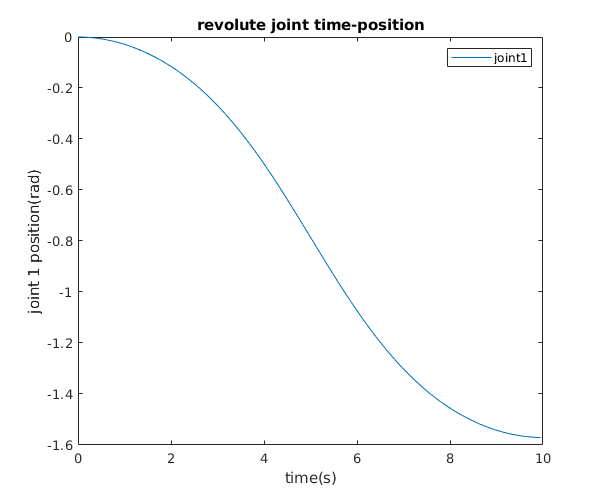

straight_q1_set = subs(q1_sol(2), t, t_vec);
straight_q2_set = subs(q2_sol(2), t, t_vec);
straight_q3_set = subs(q3_sol(2), t, t_vec);

figure(1)
plot(t_vec,straight_q1_set);
title ('revolute joint time-position')
xlabel('time(s)'), ylabel('joint 1 position(rad)')
legend('joint1')

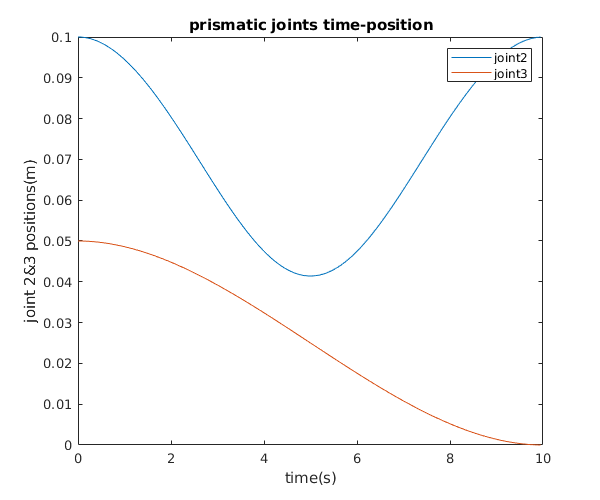


figure(2)
plot(t_vec,straight_q2_set);
hold on
plot(t_vec,straight_q3_set);
title ('prismatic joints time-position')
xlabel('time(s)'), ylabel('joint 2&3 positions(m)')
legend('joint2','joint3')

Joint 1 Velocity in radians/second and Joint 2&3 Velocities in meters/second

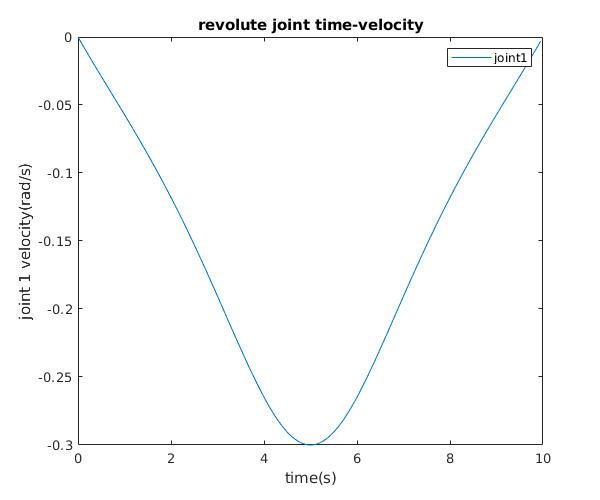

q1_vel = diff(q1_sol(2),t);
q2_vel = diff(q2_sol(2),t);
q3_vel = diff(q3_sol(2),t);

straight_q1_dot_set = subs(q1_vel, t, t_vec);
straight_q2_dot_set = subs(q2_vel, t, t_vec);
straight_q3_dot_set = subs(q3_vel, t, t_vec);

figure(3)
plot(t_vec,straight_q1_dot_set);
title ('revolute joint time-velocity')
xlabel('time(s)'), ylabel('joint 1 velocity(rad/s)')
legend('joint1')

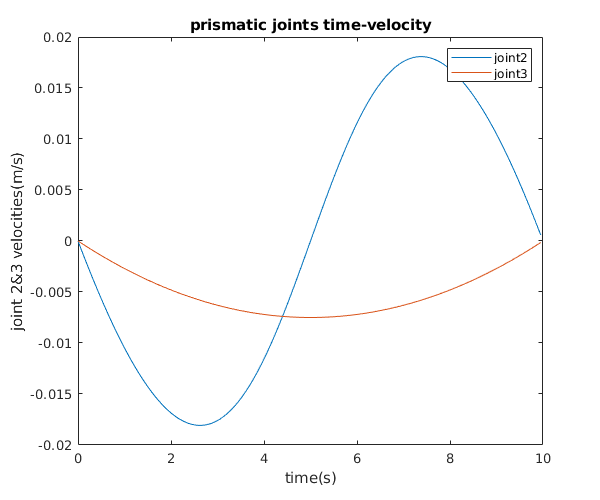


figure(4)
plot(t_vec,straight_q2_dot_set);
hold on
plot(t_vec,straight_q3_dot_set);
title ('prismatic joints time-velocity')
xlabel('time(s)'), ylabel('joint 2&3 velocities(m/s)')
legend('joint2','joint3')

Joint 1 Acceleration in radians/second square and Joint 2&3 Accelerations in meters/second square

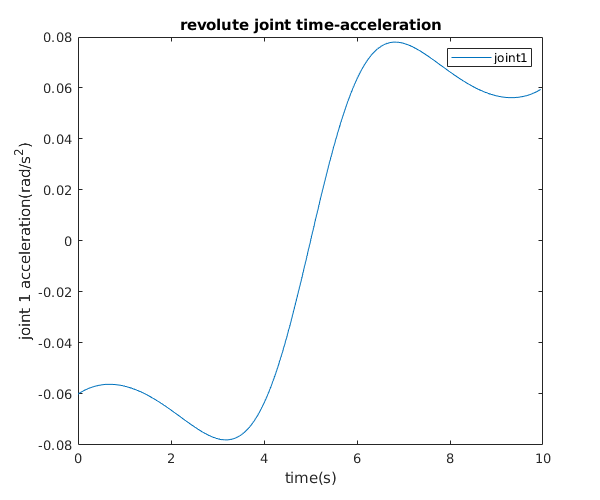

q1_acc = diff(q1_vel,t);
q2_acc = diff(q2_vel,t);
q3_acc = diff(q3_vel,t);

straight_q1_ddot_set = subs(q1_acc, t, t_vec);
straight_q2_ddot_set = subs(q2_acc, t, t_vec);
straight_q3_ddot_set = subs(q3_acc, t, t_vec);

figure(5)
plot(t_vec,straight_q1_ddot_set);
title ('revolute joint time-acceleration')
xlabel('time(s)'), ylabel('joint 1 acceleration(rad/s^2)')
legend('joint1')

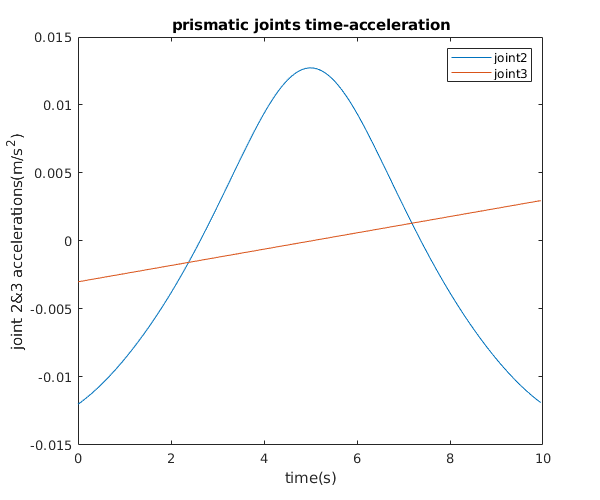


figure(6)
plot(t_vec,straight_q2_ddot_set);
hold on
plot(t_vec,straight_q3_ddot_set);
title ('prismatic joints time-acceleration')
xlabel('time(s)'), ylabel('joint 2&3 accelerations(m/s^2)')
legend('joint2','joint3')

## VERIFY TASK SPACE TRAJECTORY USING FK

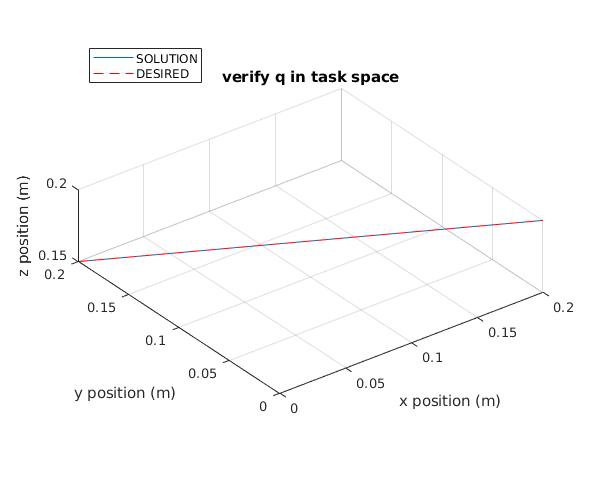

xyz = subs(P,[q1 q2 q3],[q1_sol(2) q2_sol(2) q3_sol(2)]);

%plotting our solution
xyz_set = subs(xyz, t, t_vec);
figure(7)
%plotting desired trajectory:
%a perfect line from (0,0.2,0.15) to (0.2,0,0.2) in meters
plot3(xyz_set(1,:), xyz_set(2,:), xyz_set(3,:));
hold on
plot3([0 0.2],[0.2 0],[0.15 0.2],'--r');
title('verify q in task space')
xlabel('x position (m)'), ylabel('y position (m)'), zlabel('z position (m)')
xlim([-3 3])
ylim([-3 3])
zlim([-3 3])
axis equal
grid on
legend({'SOLUTION','DESIRED'},'Location','northwest')

## FUNCTIONS

function skewMatrix = skew(a)
        skewMatrix = [0,-a(3),a(2);
        a(3),0,-a(1);
        -a(2),a(1),0];
end

function Rz = Rot_z(q)
Rz = [cos(q) -sin(q) 0; sin(q) cos(q) 0; 0 0 1];
end

function answer = chainRule(func,q,qd,qdd)
    for i = 1:length(func)
        for j = 1:length(q)
            partials(:,j) = diff(func(i),q(j)) * qd(j) + diff(func(i),qd(j)) * qdd(j);
        end
        temp(:,i) = simplify(partials);
    end
    answer = sum(temp).';
end